# **Comparison of cross-correlation techniques**

**Author**: Abakumov Ivan

Freie Universität Berlin

**E-mail: **abakumov_ivan@mail.ru

**Publication date**: 15th of May, 2018

## Introduction

In this script I compare computation of cross-correlation functions in time and in frequency domains

Cross-correlation of real functions $f$ and $g$ in time domain:


$$
C_t(\tau) =  \int_{-\infty}^{\infty} f^*(t)\ g(t+\tau)\,dt.$$


Cross-correlation of real functions $f$ and $g$ in frequency domain:


$$C_f(\tau)=\mathcal{F}^{-1}(\mathcal{F}[f])^* \cdot (\mathcal{F}[g])$$


where $\mathcal{F}$ denotes the Fourier transform.

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## **Load data (mini SEED format)**

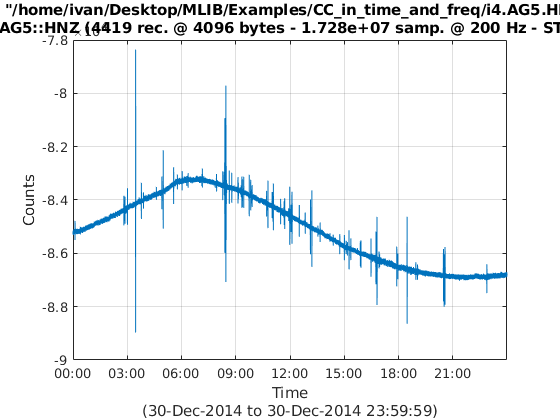

filename = [mlibfolder '/Examples/CC_in_time_and_freq/i4.AG5.HNZ.2014364_0+']; 
data = rdmseed(filename,'plot');

trace = cat(1,data.d);
time = (1:length(trace))/200/3600;     % time in hours

## Preprocessing

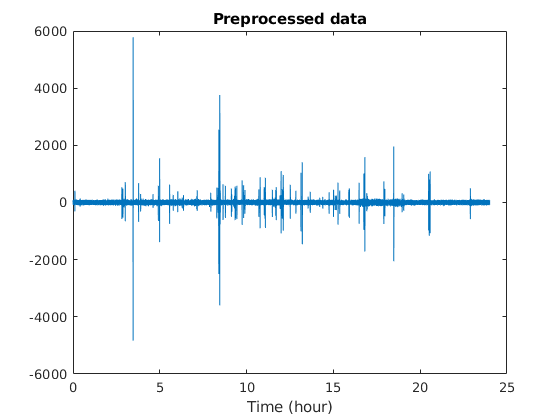

M = length(trace);                 % length of recorded trace
N = 3201;                          % length of template 
trace = trace - movmean(trace,N);  % remove trend

figure(2)
plot(time,trace);
title('Preprocessed data')
xlabel('Time (hour)')

## Create template

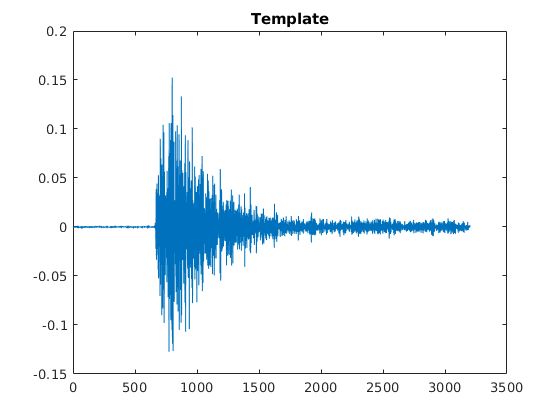

[~, ind] = max(abs(trace));
ind = ind-round(N/4)+(1:N);
template = trace(ind);
template = template - mean(template);
template = template/sqrt(sum(template.^2));

figure(3)
plot(template)
title('Template')

## Cross-correlation computed in time domain

tic
CCt = zeros(M,1);
Norm = sqrt(movsum(trace.^2,[0,N-1]));
for i=1:(M-N)
    wtrace = trace(i:(i+N-1));
    wtrace = wtrace - mean(wtrace);
    CCt(i) = sum(wtrace.*template)/Norm(i);
end
toc  

Elapsed time is 340.807878 seconds.


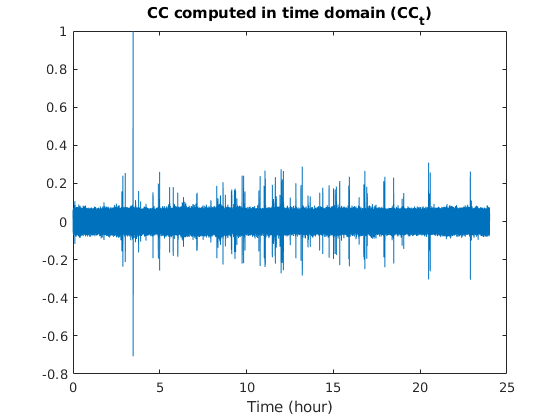


figure(4)
plot(time,CCt)
title('CC computed in time domain (CC_t)')
xlabel('Time (hour)')

## Cross-correlation computed in frequency domain

tic
Norm = sqrt(movsum(trace.^2,[0,N-1]));
CCf = xcorr(trace,template);
CCf = CCf(M:end);
CCf = CCf./Norm;
toc    

Elapsed time is 7.031225 seconds.


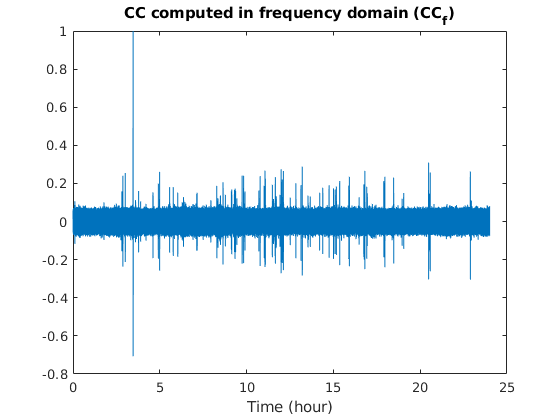


figure(5)
plot(time,CCf)
title('CC computed in frequency domain (CC_f)')
xlabel('Time (hour)')

## Compare Cross-correlation functions

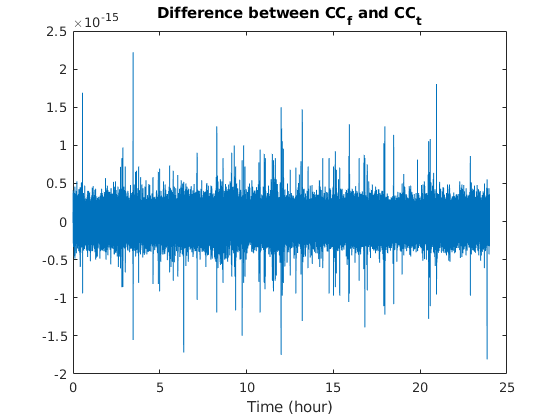

figure(6)
ind = 1:M-N;
plot(time(ind),CCf(ind)-CCt(ind))
title('Difference between CC_f and CC_t')
xlabel('Time (hour)')

## Conclusions

- CC functions computed in time and frequency domains coinside up to machine presision

- For the considered problem, computation in frequency domain is 60-70 times more efficient than in time domain (5 sec vs 320 sec)

## Remark

Buildinn MATLAB function *xcorr* is equivalent to the following procedure: